MSY_st.name='MSY'; 
MSY_st.lat=41.7795;
MSY_st.lon=2.3579;
MSY_st.alt=700;
MSY_st.env='Mt';
MSY_st.footp='Mx'

MSY_st = struct with fields:
     name: 'MSY'
      lat: 41.7795
      lon: 2.3579
      alt: 700
      env: 'Mt'
    footp: 'Mx'



MSY_rd=read_betsy('msy_2009_2018',MSY_st.name);

'read_betsy' is not found in the current folder or on the MATLAB path, but exists in:
    M:\pay-proj\pay\aerosol\matlab\gitlab_folder\trend\read_data

Change the MATLAB current folder or add its folder to the MATLAB path.

datevec(MSY_rd.Time(1))

ans =         2009           1          15           0           0           0

datevec(MSY_rd.Time(end))

ans =         2017          12          14           0           0           0

prctile(MSY_rd.U_S11,[5 50 95])

ans =    15.0000   25.6500   42.7000

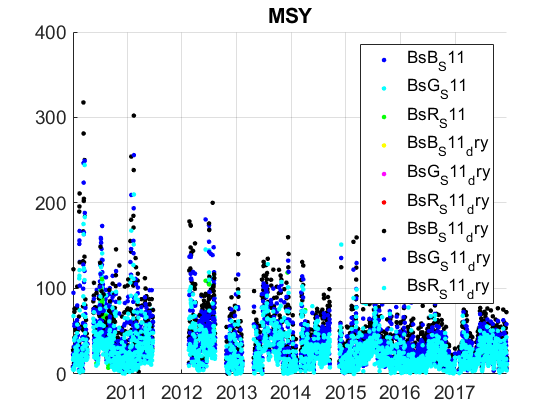

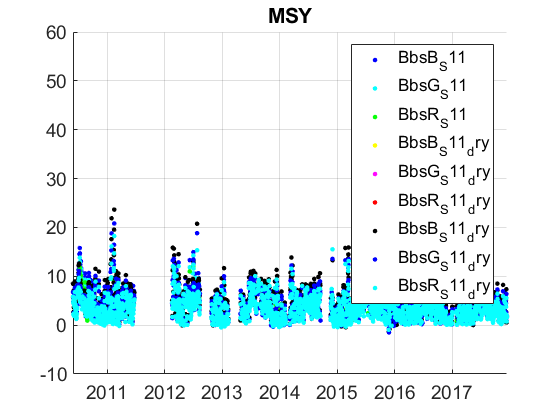

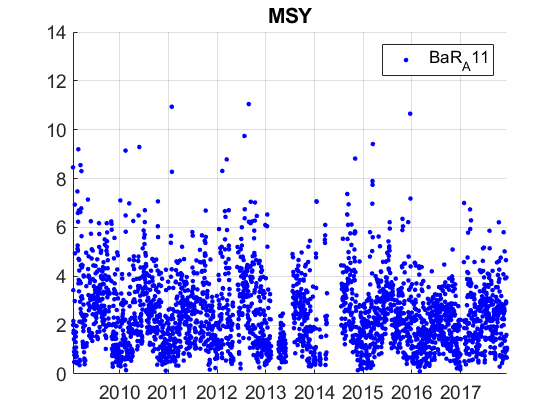

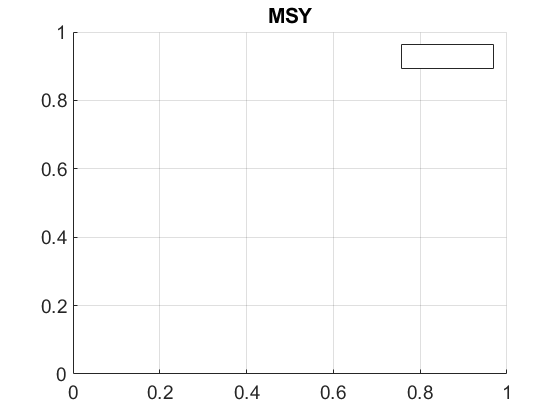

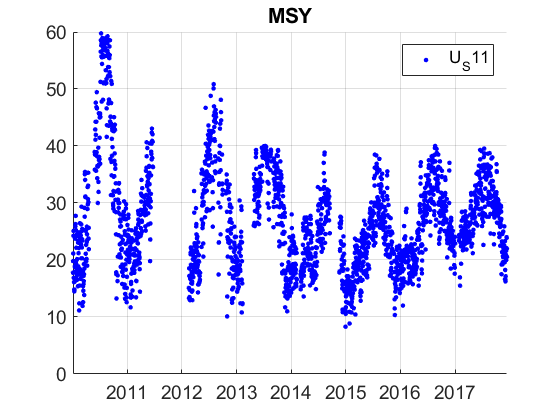

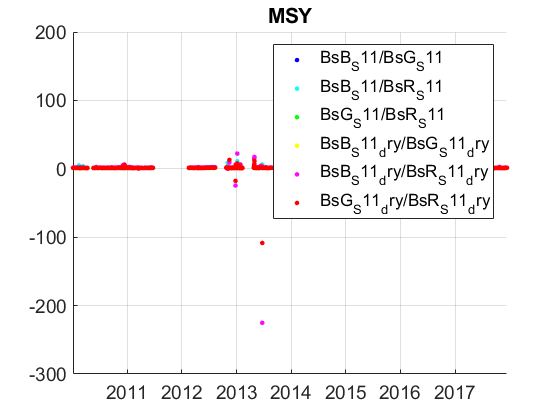

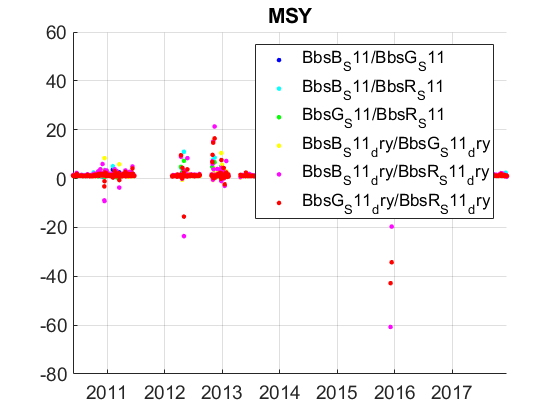

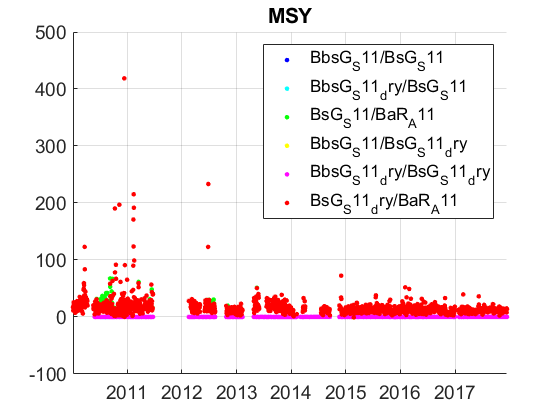

%  prctile(MSY_rd.U0_S,[5 50 95])
%  prctile(MSY_rd.U1_S,[5 50 95])
% prctile(MSY_rd.Uu1_S,[5 50 95])
plotFigControl(MSY_rd,MSY_st.name);

% 1 size cut, ok
% sc: ok, no negatives,no clear seasonal cycle

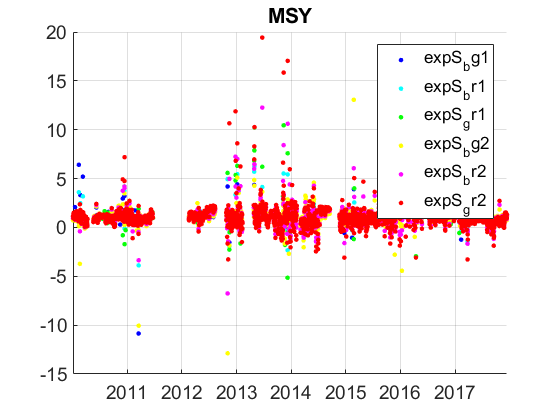

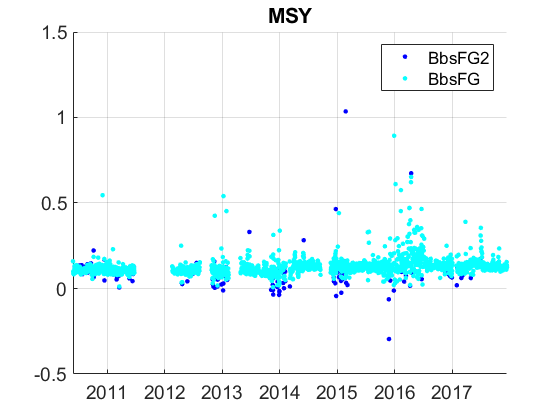

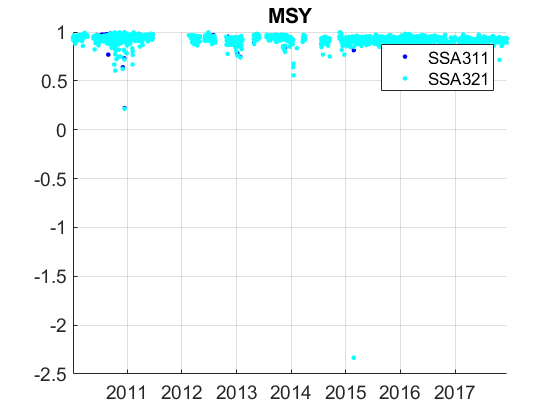

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
MSY_cal=compute_exp_SSA(MSY_rd,lambdaSC, lambdaAE);
plotFigControl_cal(MSY_cal, MSY_st.name);

%Questions:
%problems:

%RH: RH is much higher in 2010 and to a lower extend in 2012. Is it right that the humidity was controlled differently at the beginning of the time serie ? If yes, when was it changed ?

%scat: the scattering (also the dry (RH<50%) component) is correspondently higher in 2010-2011, and to a lower extend in 2012. Is there any other changes than the RH change during the two "holes" in 2011 and autumn 2012?
% It will be difficult to use the first years!
% the influence on the backscattering seems to be less important
%scat and backscat wavelength dependence: the ratio between 2 wavelengths and the scattering exponent are much more noisy between november 2015 and July 2016. Do you have an explanation ? Is there some instrumental change, calibration, intercomparison ?
% the change between nov 2015 and July 2016 is also visible in the backscattering fraction (only 1 wavelength used at a time).

%abs seems to be ok

MSY_tr=MSY_rd;
MSY_tr.y=year(MSY_tr.Time);
% begin at the beginning of a year: 2009 for abs, 2010 for scat
%end: 2018 --> only 10/9 years
 P=timerange('2009-01-01','2019-01-01');
MSY_tr=MSY_tr(P,:);

% PM1: 2012-2015: too short, not to analyse
%abs: use AE31 also only until end of 2015.
names=fieldnames(MSY_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) |  contains(names,["Q";"X";"B1_";"G1_";"R1_";"B0_A";"G0_A";"R0_A"]);
N=names(c);
for i=1:length(N)
    MSY_tr.(N{i})=[];
end
% correct abs in green for ssa trend
MSY_tr.BaR_A11=MSY_tr.BaR_A11.*(637/550);

%RH too high at the beginning: compute trend on RH and on dry
MSY_cal2=compute_exp_SSA(MSY_tr,lambdaSC, lambdaAE);
%do not compute trend on B and R
MSY_tr.BsB_S11=[];
MSY_tr.BsB_S11_dry=[];
MSY_tr.BsR_S11=[];
MSY_tr.BsR_S11_dry=[];
MSY_tr.BbsB_S11=[];
MSY_tr.BbsB_S11_dry=[];
MSY_tr.BbsR_S11=[];
MSY_tr.BbsR_S11_dry=[];
MSY_tr=outerjoin(MSY_tr, MSY_cal2);

MSY_tr.expS_br2=[];
MSY_tr.expS_br3=[];
MSY_tr.expS_gr2=[];
MSY_tr.expS_gr3=[];
%SSA is clearly decreasing, probably because of the RH decrease in the first 3 years. It seem that there is a real decrease of both scat and SSA since 2013.

MSY_result= all_trend_STN(MSY_tr,MSY_st); 

MSY_result_D=MSY_result;
%not expS_bg3 and SSA 321(dry)
s=startsWith(MSY_result_D.parameter,["expS_bg3";"SSA321"]);
MSY_result_D=MSY_result_D(~s,:);